# Calculation of Fourier coefficients for Shifted Square Wave

Exploiting half-wave symmetry

Prepared for EG-247 Signals and Systems by Chris Jobling

## Initialize problem

syms t n A pi

## Define harmonics

n = [1:11];

## DC component

half_a0 = 0

half_a0 = 0

## Compute harmonics - use half-wave symmetry

ai = 4/pi*int(A*cos(n*t),t,0,(pi/2))

$$ai = \left(\begin{array}{ccccccccccc} \frac{4\,A\,\sin\left(\frac{\pi }{2}\right)}{\pi } & \frac{2\,A\,\sin\left(\pi \right)}{\pi } & \frac{4\,A\,\sin\left(\frac{3\,\pi }{2}\right)}{3\,\pi } & \frac{A\,\sin\left(2\,\pi \right)}{\pi } & \frac{4\,A\,\sin\left(\frac{5\,\pi }{2}\right)}{5\,\pi } & \frac{2\,A\,\sin\left(3\,\pi \right)}{3\,\pi } & \frac{4\,A\,\sin\left(\frac{7\,\pi }{2}\right)}{7\,\pi } & \frac{A\,\sin\left(4\,\pi \right)}{2\,\pi } & \frac{4\,A\,\sin\left(\frac{9\,\pi }{2}\right)}{9\,\pi } & \frac{2\,A\,\sin\left(5\,\pi \right)}{5\,\pi } & \frac{4\,A\,\sin\left(\frac{11\,\pi }{2}\right)}{11\,\pi } \end{array}\right)$$

bi = zeros(size(n))

bi =      0     0     0     0     0     0     0     0     0     0     0


## Reconstruct f(t) from harmonic sine functions

ft = half_a0;
for k=1:length(n)
    ft = ft + ai(k)*cos(k*t) + bi(k)*sin(k*t);
end
ft

$$ft = \frac{2\,A\,\cos\left(2\,t\right)\,\sin\left(\pi \right)}{\pi }+\frac{4\,A\,\sin\left(\frac{\pi }{2}\right)\,\cos\left(t\right)}{\pi }+\frac{A\,\cos\left(4\,t\right)\,\sin\left(2\,\pi \right)}{\pi }+\frac{4\,A\,\cos\left(3\,t\right)\,\sin\left(\frac{3\,\pi }{2}\right)}{3\,\pi }+\frac{2\,A\,\cos\left(6\,t\right)\,\sin\left(3\,\pi \right)}{3\,\pi }+\frac{4\,A\,\cos\left(5\,t\right)\,\sin\left(\frac{5\,\pi }{2}\right)}{5\,\pi }+\frac{A\,\cos\left(8\,t\right)\,\sin\left(4\,\pi \right)}{2\,\pi }+\frac{2\,A\,\cos\left(10\,t\right)\,\sin\left(5\,\pi \right)}{5\,\pi }+\frac{4\,A\,\cos\left(7\,t\right)\,\sin\left(\frac{7\,\pi }{2}\right)}{7\,\pi }+\frac{4\,A\,\cos\left(9\,t\right)\,\sin\left(\frac{9\,\pi }{2}\right)}{9\,\pi }+\frac{4\,A\,\cos\left(11\,t\right)\,\sin\left(\frac{11\,\pi }{2}\right)}{11\,\pi }$$

## Make numeric

ft_num = subs(ft,A,1.0);
% print using 4 sig digits
ft_num = vpa(ft_num, 4)

$$ft\_num = \frac{\cos\left(4.0\,t\right)\,\sin\left(2.0\,\pi \right)}{\pi }+\frac{0.5\,\cos\left(8.0\,t\right)\,\sin\left(4.0\,\pi \right)}{\pi }+\frac{0.4444\,\cos\left(9.0\,t\right)\,\sin\left(4.5\,\pi \right)}{\pi }+\frac{0.8\,\cos\left(5.0\,t\right)\,\sin\left(2.5\,\pi \right)}{\pi }+\frac{0.4\,\cos\left(10.0\,t\right)\,\sin\left(5.0\,\pi \right)}{\pi }+\frac{0.3636\,\cos\left(11.0\,t\right)\,\sin\left(5.5\,\pi \right)}{\pi }+\frac{1.333\,\cos\left(3.0\,t\right)\,\sin\left(1.5\,\pi \right)}{\pi }+\frac{0.6667\,\cos\left(6.0\,t\right)\,\sin\left(3.0\,\pi \right)}{\pi }+\frac{0.5714\,\cos\left(7.0\,t\right)\,\sin\left(3.5\,\pi \right)}{\pi }+\frac{4.0\,\sin\left(0.5\,\pi \right)\,\cos\left(t\right)}{\pi }+\frac{2.0\,\cos\left(2.0\,t\right)\,\sin\left(\pi \right)}{\pi }$$

## plot result

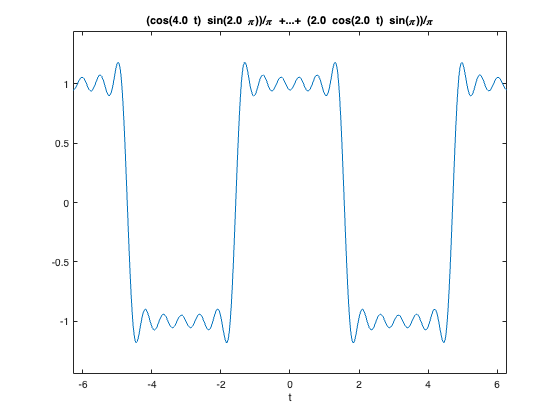

ezplot(ft_num)
hold on

## plot original signal

(we could use `heaviside` for this as well)

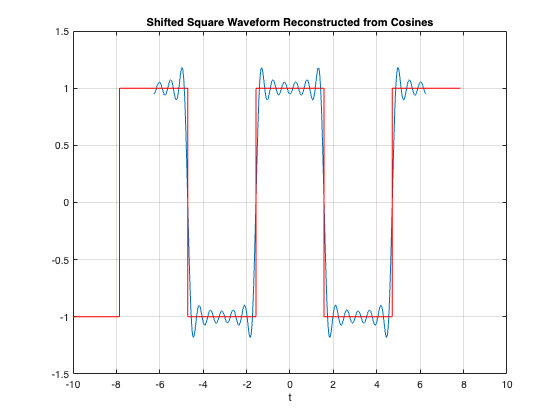

clear pi
t = [-3,-2,-2,-2,-1,-1,-1,0,0,0,1,1,1,2,2,2,3]*pi;
f = [-1,-1,0,1,1,0,-1,-1,0,1,1,0,-1,-1,0,1,1];
plot(t-pi/2,f,'r-')
axis([-10,10,-1.5,1.5])
grid
title('Shifted Square Waveform Reconstructed from Cosines')
hold off